# Práctica 1. Factorización QR

Alejandra Velasco Sánchez-Villares (51460400-Q)

## 1. Método de Gram-Schmidt

Escriba, en el Apéndice A1, una función que implemente el método de Gram-Schmidt, que responda a la sintaxis

`    [Q,R] = QRGramSchmidt(A)`

## Probando el algoritmo

A continuación se presenta algunos casos de prueba, con explicaciones. Una vez implementado el código, los siguientes casos deberían poder ejecutarse 

Se prueba con la matriz $\mathbf{A}=\left\lbrack \begin{array}{cc}
1 & 1\\
-1 & 0
\end{array}\right\rbrack$.

A = [1,1;-1,0];
[Q,R]=QRGramSchmidt(A)

Q =     0.7071    0.7071
   -0.7071    0.7071


R =     1.4142    0.7071
         0    0.7071


¿Es $\mathbf A = \mathbf Q \mathbf R$? Probar con la comparación ==

A == Q*R

ans = 2×2 logical array
   1   1
   1   1


Efectivamente coinciden.

Trabajar con números enteros es engañoso. Probar esta función con la matriz $\mathbf{A}=\left\lbrack \begin{array}{cc}
\pi  & 1\\
-1 & 0
\end{array}\right\rbrack$

¿Es $\mathbf A == \mathbf Q \mathbf R$?

A = [pi,1;-1,0];
[Q,R]=QRGramSchmidt(A)

Q =     0.9529    0.3033
   -0.3033    0.9529


R =     3.2969    0.9529
         0    0.3033


A == Q*R

ans = 2×2 logical array
   1   1
   0   1


No coinciden.

La comparación entre matrices y vectores se debe hacer siempre en norma

norm(A-Q*R)

ans = 1.1102e-16

Que efectivamente resulta casi $0$.

## 2. Método de Householder

2a. Escribir, en el Apéndice A2, una función implemente el método de Householder, que responda a la sintaxis

`    [Q,R] = QRHouseholder(A)`

Probando con la matriz $\mathbf A$ del ejercicio anterior

A = [1,1;-1,0];
[Q,R]=QRHouseholder(A);
norm(A-Q*R)

ans = 5.6569

## 3. Estudio de estabilidad

El siguiente se provee para comparar los métodos de Gram-Schmidt y Householder

La matriz del ejemplo de la comparación de estabilidad. Primero se construye unas matrices $\mathbf Q$ ortogonal y $\mathbf R$triangular superior, usando el algoritmo qr de MATLAB.

N = 80;
[U, ~] = qr(randn(N));
[V, ~] = qr(randn(N));
S = diag(2.^(-1:-1:-N));

[Q, R] = qr(U*S*V);

Se modifica la diagonal de $\mathbf R$, y se define $\mathbf A = \mathbf Q \mathbf R$

R(1:(N+1):N^2) = 2.^(-1:-1:-N);
A = Q*R;

Factorizamos con los algoritmos de Gram-Schmidt y Householder 

[QG, RG] = QRGramSchmidt(A);
[QH, RH] = QRHouseholder(A);

## Estimación en norma

Calculamos la comparación adecuada es en norma matricial

norm(A-QG*RG)

ans = 6.4825e-17

norm(A-QH*RH)

ans = 8.5337e+280

Efectivamente, en norma parece que las matrices están bien descompuestas

## Veamos qué ocurre con los elementos $r_{jj}$

Representamos los elementos diagonales en escala logarítmica

semilogy(diag(RG),'x');
hold on
semilogy(diag(RH),'o');
semilogy(abs(diag(R)),'--', 'Linewidth', 2);

Representamos el epsilon de máquina y su raíz

semilogy(sqrt(eps)*ones(N,1), 'Linewidth', 2);
semilogy(eps*ones(N,1), 'Linewidth', 2);
hold off
axis tight

Añadimos título y leyenda

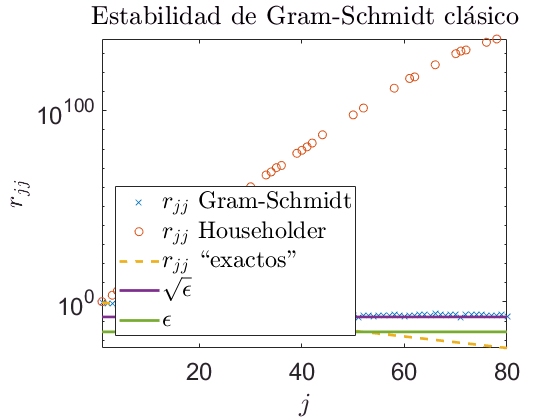

h = legend('$r_{jj}$ Gram-Schmidt',...
           '$r_{jj}$ Householder',...
           '$r_{jj}$ ``exactos''''','$\sqrt{\epsilon}$', '$\epsilon$');
set(h, 'Interpreter', 'Latex', 'FontSize', 18, 'Location', 'SouthWest')

xlabel('$j$', 'Interpreter', 'Latex');
ylabel('$r_{jj}$', 'Interpreter', 'Latex');
title("Estabilidad de Gram-Schmidt cl\'asico", 'Interpreter', 'Latex')

set(gca, 'FontSize', 18)

# Apéndice A. Sección de funciones

A1. Algoritmo de Gram Schmidt clásico para factorización QR

function [Q,R] = QRGramSchmidt(A)
    [n m] = size(A);
    Q = zeros(n,m);
    R = zeros(m);
    for j = 1:m
         Q(:,j) = A(:,j);
         if j ~= 1
             for k = 1:j-1
                 R(k,j) = Q(:,k)'*A(:,j);
                 Q(:,j) = Q(:,j) - R(k,j)*Q(:,k);
             end
         end
        R(j,j) = norm(Q(:,j));
        Q(:,j) = Q(:,j)/R(j,j);
    end
end

A2. Algoritmo de Householder para factorización QR

function [Q,R] = QRHouseholder(A)
    [n m] = size(A);
    R = A;
    Q = eye(n);
    for i = 1:m
        v = R(i:n,i)';
        v(1) = v(1) + sign(v(1))*norm(v);
        F = eye(n-i+1) - 2*(v*v')/norm(v)^2;
        Qtemp = [eye(i-1) zeros(i-1,n-i+1); zeros(n-i+1,i-1) F];
        R = Qtemp*R;
        Q = Q*Qtemp';
    end
end